# Country Patterns 

Elaborated by Natanael Bolson

Supervised by Prof. Tad Patzek and Maxim Yutkin

EGG-ANPERC-KAUST 12/2020

Description: Apply filters to find a selected country and indentify  other countries with similar characteristics

clc
clear
close all

% Select the year from 1990 to 2015
Year_T=2015;
% Here Run the algorithm that makes the cateogrical classification
run ../Patterns/Categorize.m
Pop=Data_EIA_H.Population(:,yo);
Pop(Clean)=[];

## Apply filter

% 'H' for High 'M' for Middle and 'L' for Low
% To skip filter declare as NaN
% GDP
G_F='M';
% CO2
C_F='L';
% Energy
E_F='M';
% Renewables
R_F='M';
% Land
L_F='M';
% Water
W_F='H';
% Material
M_F='L';
% HDI
H_F='M';


% Here apply the filters

if isnan(G_F)==0
    G=find(GDP_cat(:,yo)==G_F);
else
    G=GDP_cat(:,yo);
end

if isnan(C_F)==0
    C=find(CO2_cat(:,yo)==C_F);
else
    C=CO2_cat(:,yo);
end

if isnan(E_F)==0
    E=find(Exp_cat(:,yo)==E_F);
else
    E=Exp_cat(:,yo);
end

if isnan(R_F)==0
    R=find(Ren_cat(:,yo)==R_F);
else
    R=Ren_cat(:,yo);
end

if isnan(L_F)==0
    L=find(Land_cat(:,yo)==L_F);
else
    L=Land_cat(:,yo);
end

if isnan(W_F)==0
    W=find(Water_cat(:,yo)==W_F);
else
    W=Water_cat(:,yo);
end

if isnan(M_F)==0
    M=find(Mat_cat(:,yo)==M_F);
else
    M=Mat_cat(:,yo);
end

if isnan(H_F)==0
    H=find(HDI_cat(:,yo)==H_F);
else
    H=HDI_cat(:,yo);
end

% Make the intersection
Filter=intersect(G,intersect(C,intersect(E,intersect(R,intersect(L,...
    intersect(W,intersect(M,H)))))));
Country=Labels(Filter)

Country = 1×1 cell array
    {'Brazil'}


## Figure

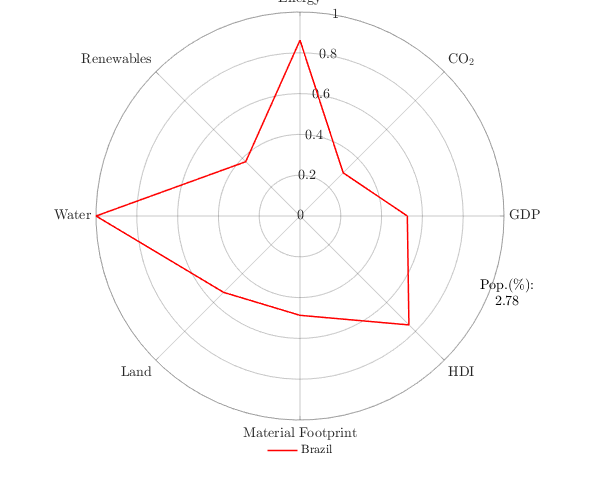

N=length(Filter); 
C=hsv(N);
i=0;
figure

for n=Filter'
    i=i+1;
    Values=Ind_S(n,:);
    X=[0,45,90,135,180,225,270,315,360]*pi/180;
    Labeltheta={'GDP','$$\mathrm{CO_2}$$','Energy','Renewables','Water','Land',...
        'Material Footprint','HDI'};
    polarplot(X,Values,'Color',C(i,:),'linewidth',1.5)
    hold on
    thetaticks(0:45:315)
    thetaticklabels(Labeltheta)
    set(gca,'Fontsize',14,'TickDir','in','FontWeight','normal','GridAlpha',0.25,...
     'LineWidth',0.2,'TickLength',[0.01 0.01],'TickLabelInterpreter','latex')

end

LegT=Labels(Filter);
ax = gca;
axPos = ax.Position;
ax.Position = axPos+ [0 0.05 0 0];

legend(LegT,'Position',[0.45 0.05 0.1 0.1],'FontSize', 12,'NumColumns',3,...
    'box','off','interpreter','latex')
set(gcf,'Position',[0 0 600 500])
Pop_C=nansum(Pop(setdiff(Filter,1)))/Pop(1)*100;
SP=sprintf('%.2f',Pop_C);
annotation('textbox', [0.845 0.45 0 0], 'String', {'Pop.(\%):';SP}, 'FitBoxToText', true,...
    'EdgeColor','none','Interpreter',"latex",'FontSize',14,'HorizontalAlignment',"center");

filename=append(char(Country(1)), '.png');
% print('-dpng','-r400',filename)